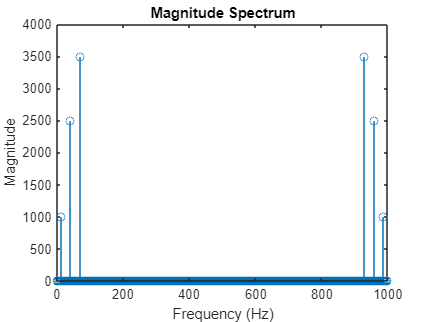

% Define the sampling frequency and time vector
Fs = 1000; % Sampling frequency in Hz
t = 0:1/Fs:1-1/Fs; % Time vector for 1 second

% Define the signal F
F = 2*cos(2*pi*15*t) + 5*cos(2*pi*40*t) + 7*cos(2*pi*70*t);

% Compute the DFT of the signal F
nfft = length(F); % Number of points in FFT
F_fft = fft(F, nfft); % DFT of signal F

% Compute the magnitude and phase of the DFT
mag_F_fft = abs(F_fft); % Magnitude
phase_F_fft = angle(F_fft); % Phase

% Frequency vector for plotting
f = (0:nfft-1)*Fs/nfft;

% Plot the magnitude spectrum
figure(1);
stem(f, mag_F_fft);
title('Magnitude Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

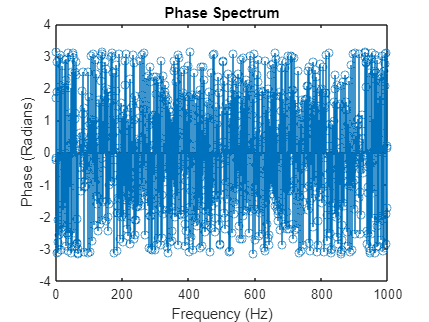

% Plot the phase spectrum
figure(2);
stem(f, phase_F_fft);
title('Phase Spectrum');
xlabel('Frequency (Hz)');
ylabel('Phase (Radians)');

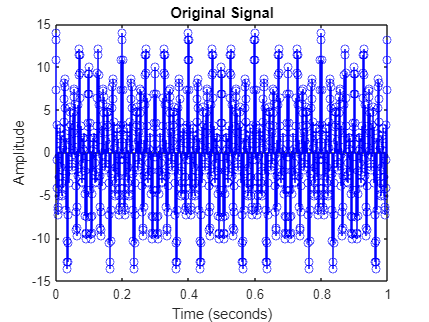


% Convert the frequency domain signal back to time domain using IFT
F_ift = ifft(F_fft, nfft);

% Plot the original and reconstructed signals to compare
figure(3);
stem(t, F, 'b');
title('Original Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');

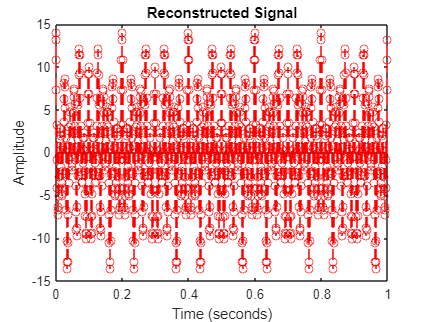

figure(4);
stem(t, F_ift, 'r--');
title('Reconstructed Signal');
xlabel('Time (seconds)');
ylabel('Amplitude');